clear;
clc;
close all;

% Load image
image = im2double(imread("images/torsten.png"));

[rows,cols,channels]=size(image);

tileSize=0.25;

imLab=rgb2lab(image);
freImage=fft2(image);
shimage=fftshift(freImage);
magSpec = abs(shimage);
magWeight = mat2gray(log(1 + magSpec));
brightnessMask = imgaussfilt(magWeight, 2);

alphaFreq = 0.5; % Strength of frequency-based adjustment
adjustmentFactor = 1 + alphaFreq * (brightnessMask - mean(brightnessMask(:)));

% Create sobel filters
sobel=fspecial('sobel')

sobel =      1     2     1
     0     0     0
    -1    -2    -1


sobelInv=-sobel

sobelInv =     -1    -2    -1
     0     0     0
     1     2     1


sobelT=fspecial('sobel')'

sobelT =      1     0    -1
     2     0    -2
     1     0    -1


sobelInvT=-sobelT

sobelInvT =     -1     0     1
    -2     0     2
    -1     0     1



% Create prewitt filters
prewitt=fspecial('prewitt')

prewitt =      1     1     1
     0     0     0
    -1    -1    -1


prewittT=prewitt'

prewittT =      1     0    -1
     1     0    -1
     1     0    -1


prewittInv=-prewitt

prewittInv =     -1    -1    -1
     0     0     0
     1     1     1


prewittInvT=-prewitt'

prewittInvT =     -1     0     1
    -1     0     1
    -1     0     1


ang45=[0 1 2;-1 0 1; -2 -1 0]

ang45 =      0     1     2
    -1     0     1
    -2    -1     0


ang45T=ang45'

ang45T =      0    -1    -2
     1     0    -1
     2     1     0


% Apply Sobel filters
output_sobel = imfilter(image, sobel);
output_sobelInv = imfilter(image, sobelInv);
output_sobelT = imfilter(image, sobelT);
output_sobelInvT = imfilter(image, sobelInvT);

% Apply Prewitt filters
output_prewitt = imfilter(image, prewitt);
output_prewittT = imfilter(image, prewittT);
output_prewittInv = imfilter(image, prewittInv);
output_prewittInvT = imfilter(image, prewittInvT);

% Apply Angle 45 filters
output_ang45 = imfilter(image, ang45);
output_ang45T = imfilter(image, ang45T);

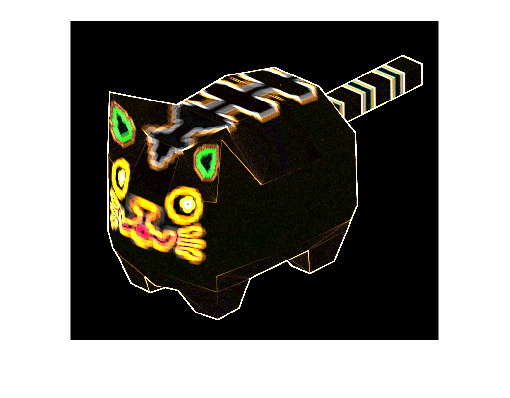

% Combine edges into a single map
edgeMap = abs(output_sobel) + abs(output_sobelInv) + abs(output_sobelT) + abs(output_sobelInvT) + abs(output_prewitt) + abs(output_prewittT) + abs(output_prewittInv) + abs(output_prewittInvT) + abs(output_ang45) + abs(output_ang45T);
figure; imshow(edgeMap);

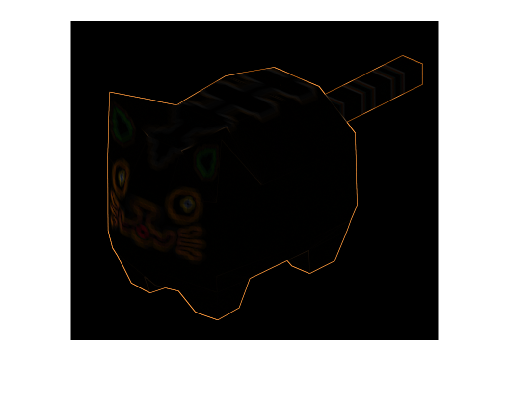


edgeMap = mat2gray(edgeMap); % Normalizes all values
figure; imshow(edgeMap);